# Ref

clear

## Definitions

### Plunger

pl_d_out   =	17.5;	% mm
pl_d_hole  =	1;    % mm
pl_height  =	15.5;	    % mm
pl_d_in    =	12;	% mm
pl_A_out   =    pl_d_out^2/4*pi;    % mm^2
pl_A_hole  =    pl_d_hole^2/4*pi    % mm^2

pl_A_hole = 0.7854

pl_A_in    =    pl_d_in^2/4*pi;    % mm^2
pl_A_u     =    pl_A_out - pl_A_in;     % mm^2
pl_m       =    0.012;  % kg
pl_rom     =    0.0059;  % m

## Design Params

load('design_params.mat');
load('micro_hs_v_electromagnetic');

### Volume

v_closed	=   3675;	% mm^3
v_open	    =   2198;	% mm^3

## Init arrays

%dt = 0.000001; % s
%T = 0.02/dt; % s
% t = zeros(T); % s
% P_ac = zeros(T); % bar
% T_ac = zeros(T); % K
% P_u = zeros(T); % bar
% T_u = zeros(T); % K
% P_d = zeros(T); % bar
% T_d = zeros(T); % K
% P_ups = zeros(T); % K
% T_ups = zeros(T); % K
% P_dps = zeros(T); % K
% T_dps = zeros(T); % K
% 
% x = zeros(T); % m
% v = zeros(T); % m/s
% a = zeros(T); % m/s^2
% 
% V_ac = zeros(T); % mm^3
% 
% pilot = zeros(T); % 1 = open, 0 = closed
% 
% A_m = zeros(T); % mm^2
% 
% m_dot_u_ups = zeros(T); % kg/s
% m_dot_ups_ac = zeros(T); % kg/s
% m_dot_ac_dps = zeros(T); % kg/s
% m_dot_ups_dps = zeros(T); % kg/s
% m_dot_dps_d = zeros(T); % kg/s
% 
% m_dot_ac_net = zeros(T); % kg/s
% m_dot_ups_net = zeros(T); % kg/s
% m_dot_dps_net = zeros(T); % kg/s
% 
% F_ac = zeros(T); % N
% F_d = zeros(T); % N
% F_u = zeros(T); % N
% F_f = zeros(T); % N
% F_s = zeros(T); % N
% F = zeros(T); % N
% 
% m_ac = zeros(T);
% m_ups = zeros(T);
% m_dps = zeros(T);

## Test Case 1

- Infinite Upstream Volume @ 400 bar 273 K

- Pipe Section after upstream @ 400 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pipe Section before downstream @ 1 bar 273 K

- Outlet external orifice D = 2 mm

- Pilot closed @ t(0)

- P_ac = 400 bar @ t(0)

- Plunger displacement x = 0 @ t(0)

dt = 1e-6; % s
T = 0.1/dt; % s
gam = 1.4;
R = 296.8; % kJ/kgK
polythropic_index = gam ;

damper = 10; % kg/s

t(1) = 0; % s
P_ups(1) = 70; % K
P_ac(1) = P_ups(1); % bar
T_ac(1) = 273; % K
P_u(1) = P_ups(1); % bar
T_u(1) = 273; % K
P_d(1) = 1; % bar
T_d(1) = 273; % K
T_ups(1) = 273; % K
P_dps(1) = 1; % K
T_dps(1) = 273; % K

x(1) = 0; % m
v(1) = 0; % m/s
a(1) = 0; % m/s^2

V_ac(1) = v_closed; % mm^3

pilot(1) = 0; % 1 = open, 0 = closed

A_m(1) = o_d_in * pi * x(1) * 10^-3; % mm^2

m_dot_u_ups(1) = 0; % kg/s
m_dot_ups_ac(1) = 0; % kg/s
m_dot_ac_dps(1) = 0; % kg/s
m_dot_ups_dps(1) = 0; % kg/s
m_dot_dps_d(1) = 0; % kg/s

m_dot_ac_net(1) = 0; % kg/s
m_dot_ups_net(1) = 0; % kg/s
m_dot_dps_net(1) = 0; % kg/s

F_ac(1) = B_to_Pa(P_ac(1)) * pl_A_out * 10^-6; % N
F_d(1) = B_to_Pa(P_dps(1)) * pl_A_in * 10^-6; % N
F_u(1) = B_to_Pa(P_ups(1)) * pl_A_u * 10^-6; % N
F_f(1) = - damper * v(1); % N
F_s(1) = 5; % N
F(1) = - F_ac(1) + F_d(1) + F_u(1) + F_f(1) - F_s(1); % N

m_ac(1) = 0.014 * B_to_Pa(P_ac(1)) * v_closed * 10^-9 / (T_ac(1) * R);
m_ups(1) = 0.014 * B_to_Pa(P_ups(1)) * V_ups * 10^-9 / (T_ups(1) * R);
m_dps(1) = 0.014 * B_to_Pa(P_dps(1)) * V_dps * 10^-9 / (T_dps(1) * R);


px(1) = 0; % m
pv(1) = 0; % m/s
pa(1) = 0; % m/s^2

%%pilot_pressure_surface = pi * (dynamic.valve.valve_seat_outlet_orifice_rad +...
%%    dynamic.valve.valve_seat_outlet_orifice_d/2)^2; %mm^2

pilot_pressure_surface = pi * (dynamic.valve.valve_seat_outlet_orifice_rad +...
    dynamic.valve.valve_seat_outlet_orifice_d/2)^2 %mm^2

pilot_pressure_surface = 3.1416


Fmag(1) = 0;
F_p_p(1) = -B_to_Pa(P_ac(1)-P_dps(1)) * pilot_pressure_surface * 10^-6; % N
K = 90e3 % N/m

K = 90000

F_p_s(1) = -(px(1) + 0.1e-3) * K;
F_p(1) = Fmag(1) + F_p_p(1) + F_p_s(1);
V_L(1) = dynamic.V; % V
pl_A_hole(1) = 0; %m^2
pl_A_hole_max = 0.25 * pi * dynamic.valve.valve_seat_outlet_orifice_d^2 * 1e-6 %m^2

pl_A_hole_max = 7.8540e-07

A_adj * 1e-6

ans = 7.0686e-08


V(1) = dynamic.V;
I(1) = 0;
[Fmag(1),N,wire_len,wire_R,sol_V(1),sol_P(1),L(1),reluctance(1)] = valve_magnetic_force(dynamic.valve,dynamic.valve.rom,I(1));
t(1) = 0;
di_dt(1) = V(1) / L(1);
total_energy(1) = 0;

old_V(1) = dynamic.V;
old_I(1) = 0;
old_di_dt(1) = 0;

for i = 2:(T-1)
    t(i) = t(i-1) + dt; % s

    signal(i) = i < (0.5*T); % 1 = open, 0 = closed

    % Old Design Magnetism
    old_I(i) = old_I(i-1) + old_di_dt(i-1) * dt;
    if (signal(i) > 0)
        applied_V = dynamic.V;
    else
        applied_V = 0;
    end
    old_V_L(i) = applied_V - old_I(i) * dynamic.R;
    [Fmag_old(i),N,wire_len,wire_R,sol_V(i),sol_P(i),L(i),reluctance(i)] =...
        valve_magnetic_force(dynamic.valve,dynamic.valve.rom - px(i-1),old_I(i));
    old_di_dt(i) = old_V_L(i) / L(i) ;

    % New Design
    I(i) = I(i-1) + di_dt(i-1) * dt;
    if (signal(i) > 0)
        applied_V = dynamic.V;
        if i < 3*dynamic.tao/dt
            applied_V = 5 * dynamic.V;
        end
    else
        applied_V = 0;
    end
    V_L(i) = applied_V - I(i) * dynamic.R;
    [Fmag(i),N,wire_len,wire_R,sol_V(i),sol_P(i),L(i),reluctance(i)] = valve_magnetic_force(dynamic.valve,dynamic.valve.rom - px(i-1),I(i));
    di_dt(i) = V_L(i) / L(i) ;
    total_energy(i) = total_energy(i-1) + I(i)^2 * dynamic.R * dt;

    F_p_s(i) = -(px(i-1) + 0.1e-3) * K;
    F_p_p(i) = -B_to_Pa(P_ac(i-1)-P_dps(i-1)) * pilot_pressure_surface * 10^-6; % N
    F_p(i) = Fmag(i) + F_p_p(i) + F_p_s(i);
    
    % Calculate displacement from previous forces
    px(i) = px(i-1) + pv(i-1)*dt + 0.5*pa(i-1)*dt^2; % m
    pv(i) = pv(i-1) + pa(i-1)*dt; % m/s
    pa(i) = F_p(i) / (dynamic.spring_rod_m+dynamic.valve_spool_m); % m/s^2
    if px(i) < 0
        px(i) = 0; % m
        pv(i) = 0; % m/s
        pa(i) = 0; % m/s^2
    elseif px(i) > dynamic.valve.rom * 1e-3
        px(i) = dynamic.valve.rom * 1e-3; % m
        pv(i) = 0; % m/s
        pa(i) = 0; % m/s^2
    end
    
    % Calculate Pilot area with new displacement
    pl_A_hole(i) = dynamic.valve.valve_seat_outlet_d * pi * px(i) * 10^-3; % m^2
    if pl_A_hole(i) > pl_A_hole_max
        pl_A_hole(i) = pl_A_hole_max;
    end

    pilot(i) = pl_A_hole(i) > 0; % 1 = open, 0 = closed

    % FluidMechanics
    P_u(i) = P_u(i-1); % bar
    T_u(i) = T_u(i-1); % K
    P_d(i) = P_d(i-1); % bar
    T_d(i) = T_d(i-1); % K
    
    % Calculate forces
    F_ac(i) = B_to_Pa(P_ac(i-1)) * pl_A_out * 10^-6; % N
    F_d(i) = B_to_Pa(P_dps(i-1)) * pl_A_in * 10^-6; % N
    F_u(i) = B_to_Pa(P_ups(i-1)) * pl_A_u * 10^-6; % N
    F_f(i) = - damper * v(i-1); % N
    F_s(i) = F_s(1); % N
    F(i) = - F_ac(i) + F_d(i) + F_u(i) + F_f(i) - F_s(i); % N
    
    % Calculate displacement from previous forces
    x(i) = x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2; % m
    v(i) = v(i-1) + a(i-1)*dt; % m/s
    a(i) = F(i) / pl_m; % m/s^2
    if x(i) < 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif x(i) > pl_rom
        x(i) = pl_rom; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end
    
    % Calculate Main area with new displacement
    A_m(i) = o_d_in * pi * x(i) * 10^-3; % m^2
    if A_m(i) > o_A_in
        A_m(i) = o_A_in;
    end
    
    % Calculate Actuation Chamber Volume after displacement
    V_ac(i) = (pl_rom - x(i)) * (v_closed - v_open) / pl_rom + v_open; % mm^3
    
    % Isentropic Compression
    P_ac(i) = P_ac(i-1) * (V_ac(i-1)/V_ac(i))^polythropic_index; % Bar
    T_ac(i) = T_ac(i-1) * (P_ac(i)/P_ac(i-1))^(1-1/polythropic_index); % K
    
    % Actuation Chamber Volume / Actuation Chamber related
    m_dot_ups_ac(i) = mdot_orifice(...
        P_ups(i-1),P_ac(i) ,polythropic_index,A_adj    *10^-6,T_ups(i-1),R); % kg/s
    m_dot_ac_dps(i) = mdot_orifice(...
        P_ac(i), P_dps(i-1),polythropic_index,pl_A_hole(i),T_ac(i), R) * (pilot(i)==1); % kg/s
    
    [P_ac(i), T_ac(i), m_ac(i)] = tank_discharge_P_io(P_ac(i),T_ac(i),m_ac(i-1),...
         [T_ups(i-1),       T_ac(i-1)],...
         [m_dot_ups_ac(i),  - m_dot_ac_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_ac_net(i) = m_ac(i) - m_ac(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_ups_dps(i) = mdot_orifice(P_ups(i-1),P_dps(i-1),polythropic_index,A_m(i),T_ups(i-1),R); % kg/s
    m_dot_u_ups(i) = mdot_orifice(P_u(i-1),  P_ups(i-1),polythropic_index,io_A    *10^-6,T_u(i-1),R); % kg/s
    
    [P_ups(i), T_ups(i), m_ups(i)] = tank_discharge_P_io(P_ups(i-1),T_ups(i-1),m_ups(i-1),...
         [T_u(i-1),        T_ups(i-1),          T_ups(i-1)],...
         [m_dot_u_ups(i),  - m_dot_ups_ac(i),   - m_dot_ups_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_ups_net(i) = m_ups(i) - m_ups(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_dps_d(i) = mdot_orifice(P_dps(i-1),P_d(i-1)  ,polythropic_index,oe_o_A    *10^-6,T_dps(i-1),R); % kg/s
    m_dot_dps_net(i) = m_dot_ac_dps(i) - m_dot_dps_d(i) + m_dot_ups_dps(i); % kg/s
    m_dps(i) = m_dps(i-1) + m_dot_dps_net(i) * dt; % kg
    [P_dps(i), T_dps(i)] = tank_discharge_P(P_dps(i-1),T_dps(i-1),m_dps(i-1),...
         - m_dot_dps_net(i) * dt,polythropic_index); % bar, K
    
    [P_dps(i), T_dps(i), m_dps(i)] = tank_discharge_P_io(P_dps(i-1),T_dps(i-1),m_dps(i-1),...
         [T_dps(i-1),        T_ac(i-1),         T_ups(i-1)],...
         [-m_dot_dps_d(i), m_dot_ac_dps(i),   m_dot_ups_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_dps_net(i) = m_dps(i) - m_dps(i-1); % kg/s
end

try
    tao3index = ceil(3*dynamic.tao/dt);
    t(tao3index)
catch
    tao3index = 1;
end

ans = 0.0271


I = I * 1e3;
old_I = old_I * 1e3;
P = I .* V_L * 1e-3;
old_P = old_I .* old_V_L * 1e-3;

## Results

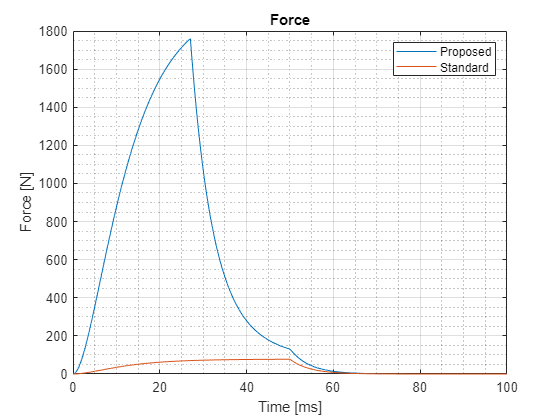

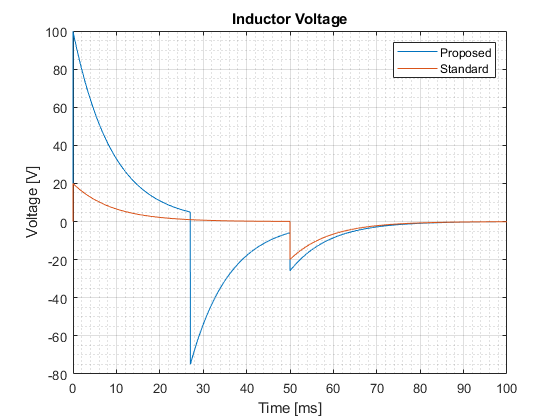

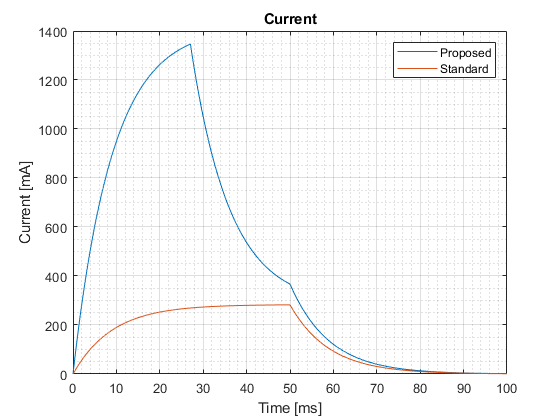

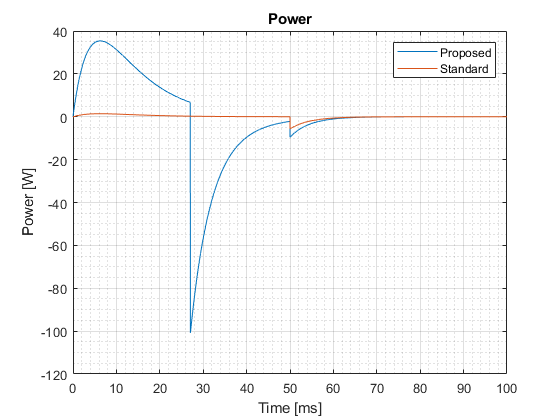

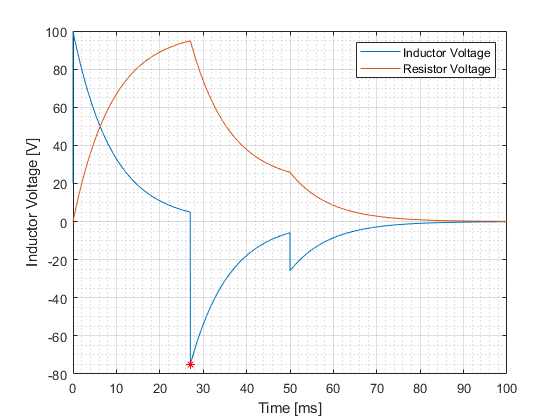

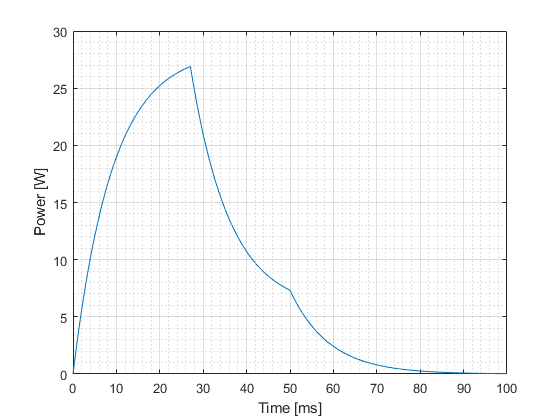

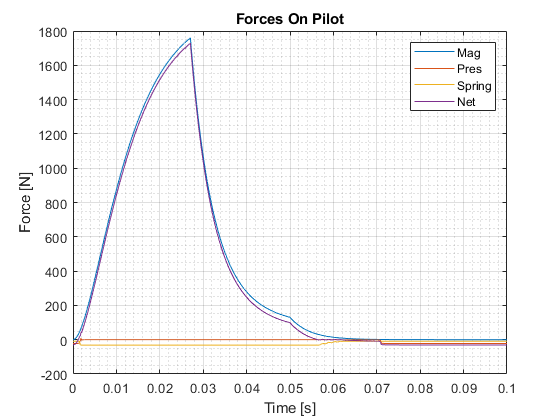

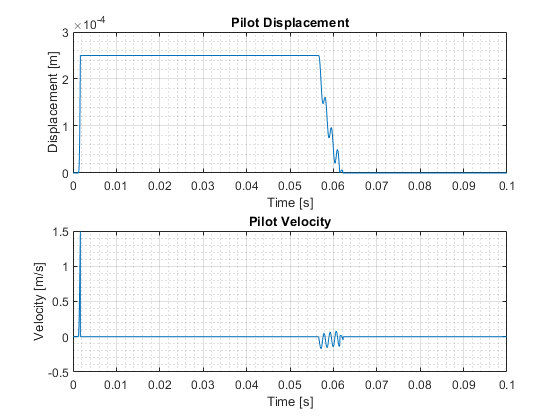

if true
    figure
    plot(t*1e3,Fmag,t*1e3,Fmag_old), legend('Proposed','Standard')
    title('Force'), xlabel('Time [ms]'), ylabel('Force [N]'), grid on, grid minor
    figure
    plot(t*1e3,V_L,t*1e3,old_V_L), legend('Proposed','Standard')
    title('Inductor Voltage'), xlabel('Time [ms]'), ylabel('Voltage [V]'), grid on, grid minor
    figure
    plot(t*1e3,I,t*1e3,old_I), legend('Proposed','Standard')
    title('Current'), xlabel('Time [ms]'), ylabel('Current [mA]'), grid on, grid minor
    figure
    plot(t*1e3,P,t*1e3,old_P), legend('Proposed','Standard')
    title('Power'), xlabel('Time [ms]'), ylabel('Power [W]'), grid on, grid minor
    figure
    plot(t*1e3,V_L,t*1e3,I*1e-3*dynamic.R,t(tao3index)*1e3,V_L(tao3index),'r*')
    legend('Inductor Voltage','Resistor Voltage')
    xlabel('Time [ms]'), ylabel('Inductor Voltage [V]'), grid on, grid minor
    figure
    plot(t*1e3,I*V_L(1)*1e-3), xlabel('Time [ms]'), ylabel('Power [W]'), grid on, grid minor
    figure
    plot(t,Fmag,t,F_p_p,t,F_p_s,t,F_p)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Force [N]'), title('Forces On Pilot')
    legend('Mag','Pres','Spring','Net')
    figure
    subplot(2,1,1)
    plot(t,px)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Displacement [m]'), title('Pilot Displacement')
    subplot(2,1,2)
    plot(t,pv)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Velocity [m/s]'), title('Pilot Velocity')
    figure
    plot(t,m_dot_ups_ac,t,m_dot_ac_dps,t,m_dot_ac_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('M dot')
    legend('U to AC', 'AC to D', 'AC net')
    figure
    plot(t,P_u,t,P_ac,t,P_d,t,P_dps,t,P_ups)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('Pressures')
    legend('U','AC','D','DPS','UPS')
    figure
    subplot(3,1,1)
    plot(t,x)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Displacement [m]'), title('Plunger Displacement')
    subplot(3,1,2)
    plot(t,V_ac)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Volume [mm^3]'), title('Actuation Chamber Volume')
    subplot(3,1,3)
    plot(t,v)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Velocity [m/s]'), title('Plunger Velocity')
    figure
    plot(t,F_ac,t,F_u,t,F_d,t,F)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Force [N]'), title('Forces On Plunger')
    legend('AC','U','D','Net')
    figure
    plot(t,m_dot_ups_dps,t,m_dot_ac_dps,t,m_dot_dps_d,t,m_dot_dps_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('DPS M dot')
    legend('UPS to DPS', 'AC to DPS', 'DPS to D', 'PDS net')
    figure
    plot(t,m_dot_u_ups,t,m_dot_ups_ac,t,m_dot_ups_dps,t,m_dot_ups_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS M dot')
    legend('U to UPS', 'UPS to AC', 'UPS to DPS', 'UPS net')
    figure
    plot(t,m_ups,t,m_dps,t,m_ac)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Mass [kg]'), title('Volume masses')
    legend('UPS', 'DPS', 'AC')
    figure
    plot(t,P_dps)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('DPS Pressure')
    figure
    plotyy(t,m_dot_dps_d,t,P_dps),legend('m_dot_dps_d','P_dps')
    figure
    plotyy(t,m_dot_u_ups,t,P_ups),legend('m_dot_dps_d','P_dps'),title('UPS'),legend('mdot','P')
    figure
    plot(t,T_u,t,T_ac,t,T_d,t,T_dps,t,T_ups)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Temperature [K]'), title('Temperatures')
    legend('U','AC','D','DPS','UPS')
    figure
    plot(t,L)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Inductance [H]'), title('Inductance')
    figure
    plot(t,reluctance)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Reluctance [1/H]'), title('Reluctance')
end

save('micro_hs_v_open_close')

## Test Case 2

- Infinite Upstream Volume @ 400 bar 273 K

- Pipe Section after upstream @ 1 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pipe Section before downstream @ 1 bar 273 K

- Outlet external orifice D = 2 mm

- Pilot closed @ t(0)

- P_ac = 1 bar @ t(0)

- Plunger displacement x = 0 @ t(0)

dt = 0.000001; % s
T = 0.03/dt; % s
gam = 1.4;
R = 296.8; % kJ/kgK
polythropic_index = gam ;

damper = 1000; % kg/s

t(1) = 0; % s
P_ac(1) = 1; % bar
T_ac(1) = 273; % K
P_u(1) = 400; % bar
T_u(1) = 273; % K
P_d(1) = 1; % bar
T_d(1) = 273; % K
P_ups(1) = 1; % K
T_ups(1) = 273; % K
P_dps(1) = 1; % K
T_dps(1) = 273; % K

x(1) = 0; % m
v(1) = 0; % m/s
a(1) = 0; % m/s^2

V_ac(1) = v_closed; % mm^3

pilot(1) = 0; % 1 = open, 0 = closed

A_m(1) = o_d_in * pi * x(1) * 10^-3; % mm^2

m_dot_u_ups(1) = 0; % kg/s
m_dot_ups_ac(1) = 0; % kg/s
m_dot_ac_dps(1) = 0; % kg/s
m_dot_ups_dps(1) = 0; % kg/s
m_dot_dps_d(1) = 0; % kg/s

m_dot_ac_net(1) = 0; % kg/s
m_dot_ups_net(1) = 0; % kg/s
m_dot_dps_net(1) = 0; % kg/s

F_ac(1) = B_to_Pa(P_ac(1)) * pl_A_out * 10^-6; % N
F_d(1) = B_to_Pa(P_dps(1)) * pl_A_in * 10^-6; % N
F_u(1) = B_to_Pa(P_ups(1)) * pl_A_u * 10^-6; % N
F_f(1) = - damper * v(1); % N
F_s(1) = 500; % N
F(1) = - F_ac(1) + F_d(1) + F_u(1) + F_f(1) - F_s(1); % N

m_ac(1) = 0.014 * B_to_Pa(P_ac(1)) * v_closed * 10^-9 / (T_ac(1) * R);
m_ups(1) = 0.014 * B_to_Pa(P_ups(1)) * V_ups * 10^-9 / (T_ups(1) * R);
m_dps(1) = 0.014 * B_to_Pa(P_dps(1)) * V_dps * 10^-9 / (T_dps(1) * R);

for i = 2:(T-1)
    t(i) = t(i-1) + dt; % s
    pilot(i) = (i > (0.333*T)) & (i < (0.666*T)); % 1 = open, 0 = closed
    
    P_u(i) = P_u(i-1); % bar
    T_u(i) = T_u(i-1); % K
    P_d(i) = P_d(i-1); % bar
    T_d(i) = T_d(i-1); % K
    
    % Calculate forces
    F_ac(i) = B_to_Pa(P_ac(i-1)) * pl_A_out * 10^-6; % N
    F_d(i) = B_to_Pa(P_dps(i-1)) * pl_A_in * 10^-6; % N
    F_u(i) = B_to_Pa(P_ups(i-1)) * pl_A_u * 10^-6; % N
    F_f(i) = - damper * v(i-1); % N
    F_s(i) = F_s(1); % N
    F(i) = - F_ac(i) + F_d(i) + F_u(i) + F_f(i) - F_s(i); % N
    
    % Calculate displacement from previous forces
    x(i) = x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2; % m
    v(i) = v(i-1) + a(i-1)*dt; % m/s
    a(i) = F(i) / pl_m; % m/s^2
    if x(i) < 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif x(i) > pl_rom
        x(i) = pl_rom; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end
    
    % Calculate Main area with new displacement
    A_m(i) = o_d_in * pi * x(i) * 10^-3; % m^2
    if A_m(i) > o_A_in
        A_m(i) = o_A_in;
    end
    
    % Calculate Actuation Chamber Volume after displacement
    V_ac(i) = (pl_rom - x(i)) * (v_closed - v_open) / pl_rom + v_open; % mm^3
    
    % Isentropic Compression
    P_ac(i) = P_ac(i-1) * (V_ac(i-1)/V_ac(i))^polythropic_index; % Bar
    T_ac(i) = T_ac(i-1) * (P_ac(i)/P_ac(i-1))^(1-1/polythropic_index); % K
    
    % Actuation Chamber Volume / Actuation Chamber related
    m_dot_ups_ac(i) = mdot_orifice(...
        P_ups(i-1),P_ac(i) ,polythropic_index,A_adj    *10^-6,T_ups(i-1),R); % kg/s
    m_dot_ac_dps(i) = mdot_orifice(...
        P_ac(i), P_dps(i-1),polythropic_index,pl_A_hole(i),T_ac(i), R) * (pilot(i)==1); % kg/s
    
    [P_ac(i), T_ac(i), m_ac(i)] = tank_discharge_P_io(P_ac(i),T_ac(i),m_ac(i-1),...
         [T_ups(i-1),       T_ac(i-1)],...
         [m_dot_ups_ac(i),  - m_dot_ac_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_ac_net(i) = m_ac(i) - m_ac(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_ups_dps(i) = mdot_orifice(P_ups(i-1),P_dps(i-1),polythropic_index,A_m(i),T_ups(i-1),R); % kg/s
    m_dot_u_ups(i) = mdot_orifice(P_u(i-1),  P_ups(i-1),polythropic_index,io_A    *10^-6,T_u(i-1),R); % kg/s
    
    [P_ups(i), T_ups(i), m_ups(i)] = tank_discharge_P_io(P_ups(i-1),T_ups(i-1),m_ups(i-1),...
         [T_u(i-1),        T_ups(i-1),          T_ups(i-1)],...
         [m_dot_u_ups(i),  - m_dot_ups_ac(i),   - m_dot_ups_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_ups_net(i) = m_ups(i) - m_ups(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_dps_d(i) = mdot_orifice(P_dps(i-1),P_d(i-1)  ,polythropic_index,oe_o_A    *10^-6,T_dps(i-1),R); % kg/s
    m_dot_dps_net(i) = m_dot_ac_dps(i) - m_dot_dps_d(i) + m_dot_ups_dps(i); % kg/s
    m_dps(i) = m_dps(i-1) + m_dot_dps_net(i) * dt; % kg
    [P_dps(i), T_dps(i)] = tank_discharge_P(P_dps(i-1),T_dps(i-1),m_dps(i-1),...
         - m_dot_dps_net(i) * dt,polythropic_index); % bar, K
    
    [P_dps(i), T_dps(i), m_dps(i)] = tank_discharge_P_io(P_dps(i-1),T_dps(i-1),m_dps(i-1),...
         [T_dps(i-1),        T_ac(i-1),         T_ups(i-1)],...
         [-m_dot_dps_d(i), m_dot_ac_dps(i),   m_dot_ups_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_dps_net(i) = m_dps(i) - m_dps(i-1); % kg/s
end


## Results

if false
    figure
    plot(t,m_dot_ups_ac,t,m_dot_ac_dps,t,m_dot_ac_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('M dot')
    legend('U to AC', 'AC to D', 'AC net')
    figure
    plot(t,P_u,t,P_ac,t,P_d,t,P_dps,t,P_ups)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('Pressures')
    legend('U','AC','D','DPS','UPS')
    figure
    subplot(3,1,1)
    plot(t,x)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Displacement [m]'), title('Plunger Displacement')
    subplot(3,1,2)
    plot(t,V_ac)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Volume [mm^3]'), title('Actuation Chamber Volume')
    subplot(3,1,3)
    plot(t,v)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Velocity [m/s]'), title('Plunger Velocity')
    figure
    plot(t,F_ac,t,F_u,t,F_d,t,F)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Force [N]'), title('Forces On Plunger')
    legend('AC','U','D','Net')
    figure
    plot(t,m_dot_ups_dps,t,m_dot_ac_dps,t,m_dot_dps_d,t,m_dot_dps_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('DPS M dot')
    legend('UPS to DPS', 'AC to DPS', 'DPS to D', 'PDS net')
    figure
    plot(t,m_dot_u_ups,t,m_dot_ups_ac,t,m_dot_ups_dps,t,m_dot_ups_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS M dot')
    legend('U to UPS', 'UPS to AC', 'UPS to DPS', 'UPS net')
    figure
    plot(t,m_ups,t,m_dps,t,m_ac)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Mass [kg]'), title('Volume masses')
    legend('UPS', 'DPS', 'AC')
    figure
    plot(t,P_dps)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('DPS Pressure')
    figure
    plotyy(t,m_dot_dps_d,t,P_dps),legend('m_dot_dps_d','P_dps')
    figure
    plotyy(t,m_dot_u_ups,t,P_ups),legend('m_dot_dps_d','P_dps'),title('UPS'),legend('mdot','P')
    figure
    plot(t,T_u,t,T_ac,t,T_d,t,T_dps,t,T_ups)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Temperature [K]'), title('Temperatures')
    legend('U','AC','D','DPS','UPS')
end
save('micro_hs_v_fill_open_close')